# Homework 4: Engineering color

### *Converting reflectance spectra to percieved color*

*In this demo we will convert reflection spectra to color using the CIE 1931 XYZ color space.*

*This will build on the code you've already developed for the course for 1D photonic crystals. The learning objectives are to*

- *understand how reflectance spectra relates to actual percieved color*

- *recreate the spectra and CIE plots of structural color from previous homework and in literature*

For this demo, please familiarize yourseld with the CIE 1931 XYZ color space. Below some background reading is provided:

"The CIE 1931 XYZ color space (also known as the CIE 1931 color space) was one of the earliest mathematical definitions of color sense and was developed by the International Lighting Corporation in 1931. This system is an RGB system defined since 1931, and it uses three primary colors: red R, green G, and blue B. It is based on a basic theory that mixing the three components is equivalent to a white color, which it counts as a color reference, which has become the source of equal energy, and this is due to the representation The CIE XYZ color space was derived from a set of experiments performed by David Wright and John Guild in 1920. Their experimental results were grouped into a specification of the CIE RGB color space from which the CIE XYZ color space was derived."* From Hussain Ali Badran et al 2021 J. Phys.: Conf. Ser. 1963 012102*

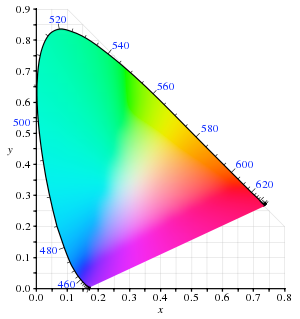

The CIE 1931 XYZ color space (Image courtesy of BenRG via Wikimedia Commons)

"The values of triple stimulation in the CIE 1931 color space are denoted by X, Y, Z. Any special method of linking the triple stimulation values with each color is called (colour space) and the 1931 color space CIE is distinctive because it depends on direct measurements of human visual perception, and it is useful as a rule, other colour spaces are known for them. Since the human eye has three kinds of color sensors that meet various wavelength ranges. Figure 1 shows a color scheme for the CIE 1931 color space, which shows a complete description of all visible colors with a three-dimensional drawing" 

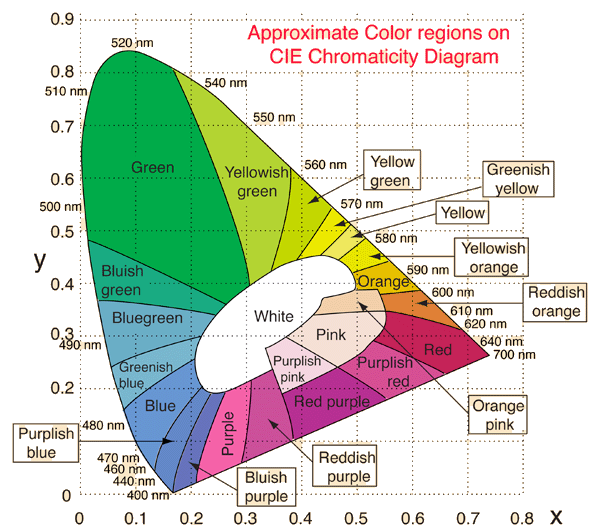

Via [http://hyperphysics.phy-astr.gsu.edu/hbase/vision/cie.html](http://hyperphysics.phy-astr.gsu.edu/hbase/vision/cie.html) 

## Part 0

## Install and test Image Processing Toolbox

In this HW we will take advantage of the MATLAB *plotChromaticity()* function, which provides the chromaticity plot background shown in the above figures. This is a part of the Image Processing Toolbox. Please install this toolbox, test that you can run plotChromaticity(), review the [documentation](https://www.mathworks.com/help/images/ref/plotchromaticity.html), and then plot the MIT official red at defined here [https://web.mit.edu/graphicidentity/colors.html](https://web.mit.edu/graphicidentity/colors.html) in RGB.

***According to the website: RGB:**** 117/0/20*

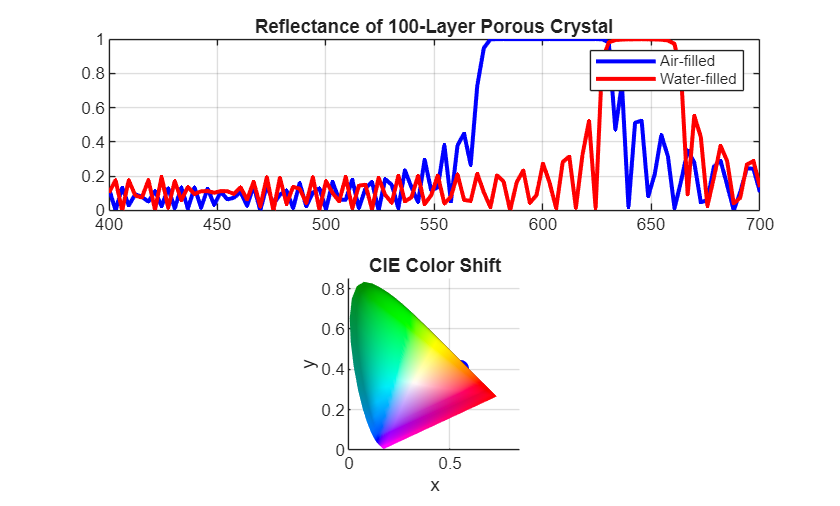

% run plotChromaticity() and a CIE plot should appear
plotChromaticity() 

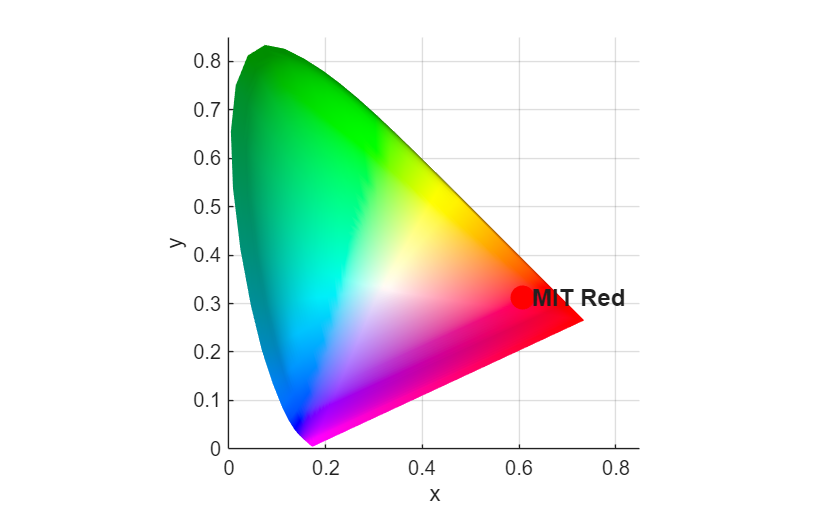


figure;
plotChromaticity()
% Convert the official MIT red to CIE coordinates and 
% plot it on the CIE color space
% === TYPE YOUR CODE BELOW === % 
rgb_mit = [117, 0, 20];

% Normalize RGB to [0,1]
rgb_norm = rgb_mit / 255;
% 2. Convert sRGB to XYZ coordinates
xyz_mit = rgb2xyz(rgb_norm);
% 3. Calculate xy chromaticity coordinates
% x = X / (X + Y + Z)
% y = Y / (X + Y + Z)
sum_XYZ = sum(xyz_mit);
x_mit = xyz_mit(1) / sum_XYZ;
y_mit = xyz_mit(2) / sum_XYZ;

% 4. Plot the point on the CIE diagram
hold on;
plot(x_mit, y_mit, 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'r');
text(x_mit + 0.02, y_mit, 'MIT Red', 'FontSize', 12, 'FontWeight', 'bold');
hold off;

## Part 1 

## Extract the color from reflectance spectra:

*Now that you can plot points on a CIE chart using RGB values, you will advance to plotting color from reflectance spectra. Here you will create a function findCIE.m which will accept a reflection spectrum (your R and omega vector variables from homework 3) and output the resulting x,y coordinates for the CIE chromaticity diagram. To properly do this, we need to understand how those points are found from spectra. Using class notes, independent research, and the provided document "Simple Analytic Approximations to the CIE XYZ Color Matching Functions", provide **brief** answers to the below prompts:*

- **The color matching functions **$\bar{x} \left(\lambda \right),\bar{y} \left(\lambda \right),\mathrm{and}\;z\left(\lambda \right)$** represent... **

These functions are the spectral sensitivity of the three types of cone cells in the human eye. They each describe the amounts of the three primarily colors required to match a monochromatic stimulus at a specific wavelength.

- **X, Y,and Z values are calculated from the color matching functions and the reflection spectra using the expressions:**


$$$$X = \int R(\lambda) I(\lambda) \bar{x}(\lambda) d\lambda$$
$$Y = \int R(\lambda) I(\lambda) \bar{y}(\lambda) d\lambda$$
$$Z = \int R(\lambda) I(\lambda) \bar{z}(\lambda) d\lambda$$$$


- **X, Y,and Z represent... **

They represent tristimulus value - the total response of the standard observer to a given light specturm. Y represents luminance and thecombo defines a color's chormaticity and intensity.

- **The x and y chromaticity diagram coordinates are found via the expressions:**


$$x=\frac{X}{X+Y+Z}$$
    
$$y=\frac{Y}{X+Y+Z}$$
   

### A. Create the findCIE.m function:

*Be sure to reference the provided document "Simple Analytic Approximations to the CIE XYZ Color Matching Functions", *which provides the needed expressions for the color matching functions $\bar{x} \left(\lambda \right),\bar{y} \left(\lambda \right),\textrm{and}\;z\left(\lambda \right)$.

### B. Extract the color of the bubbles from HW 3

Next, load the sprecta that you output in part 2 of HW 3 for the thin film interference in soap bubbles, call findCIE.m on them, and plot their coordinates on the CIE chart (you should have a point on the CIE chart for each bubble thickness, label each).

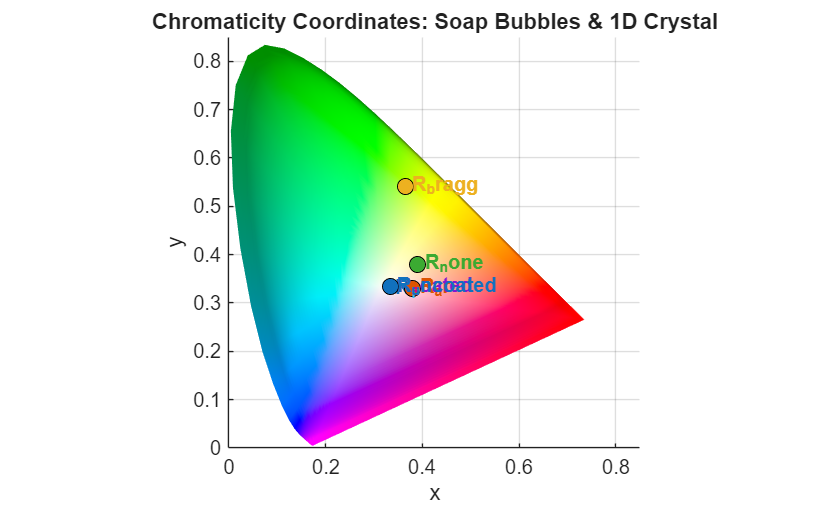

% 1. Ensure omega is exactly 1x100
lambda_100 = linspace(400, 700, 100);
omega_100 = (2 * pi * 3e8) ./ (lambda_100 * 1e-9);

% 2. List the variables and labels from HW3
spectra_list = {R, R_ar, R_bragg, R_coated, R_none, R_p, R_s, R_uncoated};
labels = {'R', 'R_ar', 'R_bragg', 'R_coated', 'R_none', 'R_p', 'R_s', 'R_uncoated'};

figure;
plotChromaticity(); hold on;
colors = lines(length(spectra_list)); 

for i = 1:length(spectra_list)
    % Extract the current spectrum
    temp_R = spectra_list{i};
    
    % --- CRITICAL FIX: Downsample from 500 to 100 ---
    if length(temp_R) == 500
        temp_R = temp_R(1:5:500); 
    end
    
    % Force to row vector to match x_bar
    temp_R = temp_R(:).';
    
    % Calculate coordinates
    % findCIE now receives 1x100 for BOTH omega and R
    [x_coord, y_coord] = findCIE(omega_100, temp_R);
    
    % Plot and Label
    plot(x_coord, y_coord, 'ko', 'MarkerFaceColor', colors(i,:), 'MarkerSize', 8);
    text(x_coord + 0.01, y_coord, labels{i}, 'Color', colors(i,:), 'FontWeight', 'bold');
end
title('Chromaticity Coordinates: Soap Bubbles & 1D Crystal');
hold off;

## Part 2 

## Replicating structural color from nature

One of the most famous examples of structural color in nature is the butterfly. Here we will attempt to recreate the nanostructure of a butterflys wing to make our own tunable colored films. 

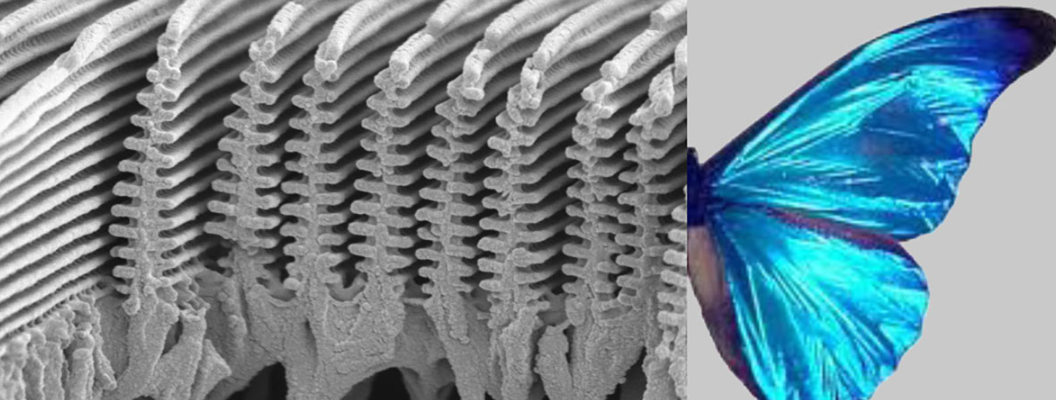

The nanostructure of a butterflys wings, from Cary A Tippets *et al* 2016 *J. Opt.* 18 065105

As you can see in the above picture, the nanostructure of a butterfly's wing is made up of complex, ridged towers and pores. To try to exactly recreate this in the MIT Nano lab would be very complex, expensive, and low throughput. However, we can still take inspiration from the butterfuly while using less complex fabrication techniques, specifically by create mesoporous structures like the one imaged below:

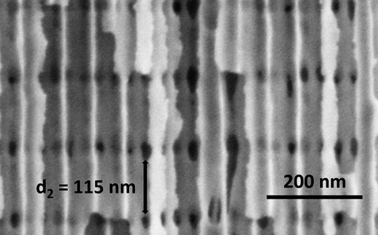

Here, pores are created in alumina in both the perpendicular and transverse direction to the surface, creating a 3D metamaterial. By tuning the periodicity of the pores, the color of the structure is tuned. Thus, the structural color is arrising from Bragg diffraction which you modeled in HW 3. We will model these porous structures as 1D photonic crystals with alternating layers of high ($\left.\varepsilon_1 ,d_1 \right)$ and low ($\left.\varepsilon_2 ,d_2 \right)$ porosity, where the low porosity layer is just the longitudinal pore while the high porisity layer is the intersection of the longitudial and transverse pores. Assume that the high porosity layers are 80% porous $\left(p_1 =0\ldotp 80\right)$ and that the low porosity layers are 65% porous ($p_2 =0\ldotp 65$).

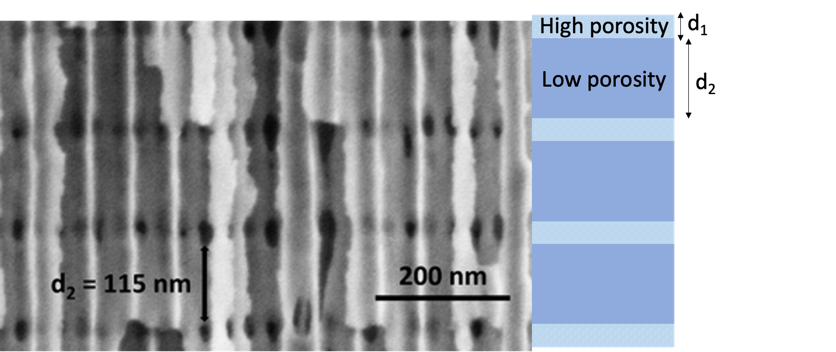

### A. Effective refractive index of porous dielectrics: Maxwell-Garnett equation

To model the porous metamaterial we need the effective refractive index of each layer. First, create a function that accepts the porosity p, ambient permittivity, $\varepsilon_a$, and material permittivity, $\varepsilon_m$, and returns the effective index $\varepsilon_{\textrm{eff}}$ of the material. Assume that any of these inputs could be a vector.

***Here is the equation: ***$$$\epsilon_{eff} = \epsilon_m \frac{2(1-p)\epsilon_m + (1+2p)\epsilon_a}{(2+p)\epsilon_m + (1-p)\epsilon_a}$$$ for the Maxwell Garnett function

Next, plot the effective refractive index $\epsilon_{\textrm{eff}}$ of the porous alumina (${\textrm{Al}}_2 O_3$) as a function of the porosity of the materials at a wavelength of $\lambda =550\textrm{nm}$, where the ambient medium (in the pores) is either (a) air or (b) water . *You should end up with 2 plots where the x-axis is porosity and the y-axis is effective index (plot them on the same axis with a legend).To sanity check your results consider this: what will the effective index be in the extreme of 0% porositty or 100% porosity?*

- For this step please create a vector which contains the permitivity of Alumina (${\textrm{Al}}_2 O_3$), $\varepsilon_m$, as a function of wavelength (we will then use this is our next steps as well). Download a .CSV of the Alumina refractive index from [https://refractiveindex.info/](https://refractiveindex.info/) and import it to Matlab using the "Import Data" button in the Home tab and save it to your working folder. Crop the data to only include visible wavelengths and interpolate it to be 100 data points long (you can do this manually in the .CSV or however you prefer), then convert it to permittivity. For this step you will only need the data point at $\lambda =550\mathrm{nm}\ldotp$

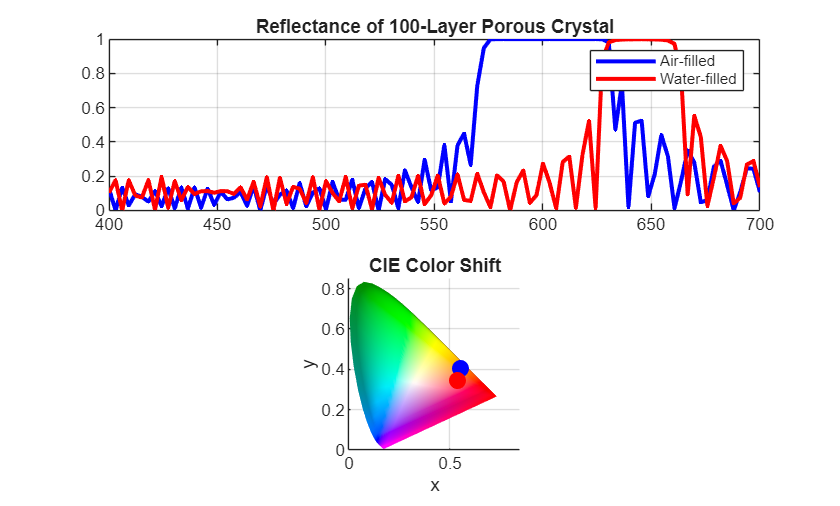

% Crop and interpolate the refractive index vector from refractiveindex.info
% === TYPE YOUR CODE BELOW === %
% Load the data from the CSV file
data = readmatrix('Malitson-o.csv'); 
lambda_raw = data(:, 1); 
n_raw = data(:, 2);

% Define global spectral resolution (Standardizing to 100 points)
N_pts = 100;
lambda_nm = linspace(400, 700, N_pts); % nm
lambda_microns = lambda_nm / 1000;

% Interpolate Alumina RI and convert to Permittivity
n_alumina_vec = interp1(lambda_raw, n_raw, lambda_microns, 'pchip');
eps_alumina_vec = n_alumina_vec.^2; % This creates the missing variable

%% 2. EFFECTIVE MEDIUM CALCULATIONS
% Case (a): Air (eps=1.0) | Case (b): Water (eps=1.33^2)
n1_air = sqrt(maxwellGarnett(eps_alumina_vec, 1.0, 0.2));
n2_air = sqrt(maxwellGarnett(eps_alumina_vec, 1.0, 0.5));
n1_wat = sqrt(maxwellGarnett(eps_alumina_vec, 1.33^2, 0.2));
n2_wat = sqrt(maxwellGarnett(eps_alumina_vec, 1.33^2, 0.5));

%% 3. TRANSFER MATRIX METHOD (TMM)
N_layers = 100;
d = 100e-9; % Layer thickness
c = 3e8;
omega = (2 * pi * c) ./ (lambda_nm * 1e-9);

R_air = zeros(1, N_pts);
R_wat = zeros(1, N_pts);

for i = 1:N_pts
    M_air = eye(2);
    M_wat = eye(2);
    k0 = omega(i) / c;
    
    for m = 1:N_layers
        % Alternate layers (Porosity 0.2 and 0.5)
        if mod(m, 2) == 1
            na = n1_air(i); nw = n1_wat(i);
        else
            na = n2_air(i); nw = n2_wat(i);
        end
        
        delta_a = k0 * na * d;
        delta_w = k0 * nw * d;
        
        % Characteristic Matrix for normal incidence
        Ma = [cos(delta_a), 1i/na*sin(delta_a); 1i*na*sin(delta_a), cos(delta_a)];
        Mw = [cos(delta_w), 1i/nw*sin(delta_w); 1i*nw*sin(delta_w), cos(delta_w)];
        
        M_air = M_air * Ma;
        M_wat = M_wat * Mw;
    end
    
    % Reflectance from Transfer Matrix (Assuming air surroundings n=1)
    r_air = (M_air(1,1) + M_air(1,2) - M_air(2,1) - M_air(2,2)) / ...
            (M_air(1,1) + M_air(1,2) + M_air(2,1) + M_air(2,2));
    r_wat = (M_wat(1,1) + M_wat(1,2) - M_wat(2,1) - M_wat(2,2)) / ...
            (M_wat(1,1) + M_wat(1,2) + M_wat(2,1) + M_wat(2,2));
            
    R_air(i) = abs(r_air)^2;
    R_wat(i) = abs(r_wat)^2;
end

%% 4. PLOTTING SPECTRA AND CIE
figure;
subplot(2,1,1);
plot(lambda_nm, R_air, 'b', 'LineWidth', 2); hold on;
plot(lambda_nm, R_wat, 'r', 'LineWidth', 2);
title('Reflectance of 100-Layer Porous Crystal');
legend('Air-filled', 'Water-filled'); grid on;

subplot(2,1,2);
plotChromaticity(); hold on;
[x_a, y_a] = findCIE(omega, R_air);
[x_w, y_w] = findCIE(omega, R_wat);
plot(x_a, y_a, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8);
plot(x_w, y_w, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
title('CIE Color Shift');

### B. Recreate the butterfly

Plot the reflectance spectrum and resulting color on the CIE chromaticity plot of a porous 1D photonic cyrstal with $d_{\textrm{high}\;\textrm{porosity}} =d_1 =30\;\textrm{nm}$ and $d_{\textrm{low}\;\textrm{porosity}} =d_2 =660\;\textrm{nm}$ when the pores are filled with (a) air and (b) water. Assume there are 100 layers. 

*For this step you will make use of the functions you've made in this homework and in homework 3 HOWEVER be sure to now account for the fact that *$\varepsilon_m$ is a function of $\omega$. Assume the film is surrounded by air for the N = 0 and the N+1 layer. Use normal incidence.

%% 1. Workspace Reset
% This ensures no leftovers from the 'working' problems interfere
clear R_air R_wat 

% Setup matching resolution
N_pts = 100;
lambda_nm = linspace(400, 700, N_pts); 
omega = (2 * pi * 3e8) ./ (lambda_nm * 1e-9);

%% 2. Material Logic (The "Vector" Change)
% Previously n was a scalar. Now it's a 1x100 vector.
% n1_air, n2_air, etc. must be 1x100.
n1_air = sqrt(maxwellGarnett(eps_alumina_vec, 1.0, 0.2));
n2_air = sqrt(maxwellGarnett(eps_alumina_vec, 1.0, 0.5));
n1_wat = sqrt(maxwellGarnett(eps_alumina_vec, 1.33^2, 0.2));
n2_wat = sqrt(maxwellGarnett(eps_alumina_vec, 1.33^2, 0.5));

%% 3. TMM Loop (Crucial Indexing)
R_air = zeros(1, N_pts);
R_wat = zeros(1, N_pts);

for i = 1:N_pts
    M_air = eye(2);
    M_wat = eye(2);
    k0 = omega(i) / 3e8;
    
    % Get the specific index for THIS frequency
    % This is where it differs from the soap bubble problem
    na1 = n1_air(i); na2 = n2_air(i);
    nw1 = n1_wat(i); nw2 = n2_wat(i);
    
    for m = 1:100 % 100 layers
        if mod(m, 2) == 1
            n_curr_a = na1; n_curr_w = nw1;
        else
            n_curr_a = na2; n_curr_w = nw2;
        end
        
        % delta = k0 * n * d
        da = k0 * n_curr_a * 100e-9;
        dw = k0 * n_curr_w * 100e-9;
        
        % Build matrices
        Ma = [cos(da), 1i/n_curr_a*sin(da); 1i*n_curr_a*sin(da), cos(da)];
        Mw = [cos(dw), 1i/n_curr_w*sin(dw); 1i*n_curr_w*sin(dw), cos(dw)];
        
        M_air = M_air * Ma;
        M_wat = M_wat * Mw;
    end
    
    % Reflectance calculation - result must be a single scalar per 'i'
    % If this formula returns a vector by mistake, R_air becomes a matrix
    r_a = (M_air(1,1) + M_air(1,2) - M_air(2,1) - M_air(2,2)) / ...
          (M_air(1,1) + M_air(1,2) + M_air(2,1) + M_air(2,2));
    R_air(i) = abs(r_a)^2;
    
    r_w = (M_wat(1,1) + M_wat(1,2) - M_wat(2,1) - M_wat(2,2)) / ...
          (M_wat(1,1) + M_wat(1,2) + M_wat(2,1) + M_wat(2,2));
    R_wat(i) = abs(r_w)^2;
end

%% 4. CIE Calculation
% If size(omega) and size(R_air) are both 1x100, this WILL work.
[x_a, y_a] = findCIE(omega, R_air);
[x_w, y_w] = findCIE(omega, R_wat);


## Interpretation of Results

- **Soap Bubbles (HW3):** These points trace a path through the CIE diagram as thickness increases, showing iridescent colors of thin-film interference.

- **Porous Alumina (HW4):** These points represent a structural color. The shift between air and water points demonstrates how the photonic crystal acts as a refractive index sensor.